# 2.2.2 

clear all; close all;
range_ramp=0:1:255;
s_ramp = repmat(range_ramp,256,1);
% create sin 2x and 2y img
x = 1:256;
y = 1:256;
y =y';
fs = 256;
ts=1/fs;
fx_y = 2; 
image_x = 127-127*cos(2*pi*fx_y*ts*x);
image_x = repmat(image_x,256,1);
image_y = 127-127*cos(2*pi*fx_y*ts*y);
image_y = repmat(image_y,1,256);
s_2x_2y = uint8((image_x + image_y)/2);

ramp quant 1,2,3,4

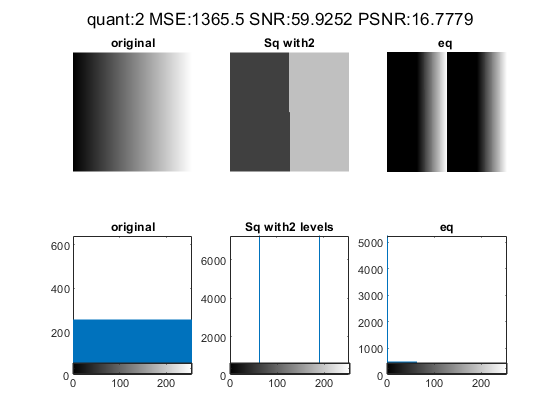

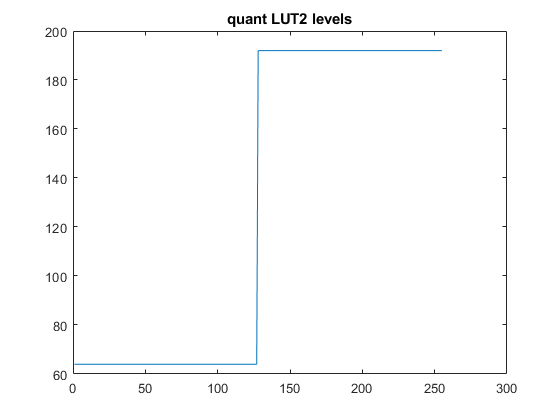

figure();
plot_quant(s_ramp, 2);

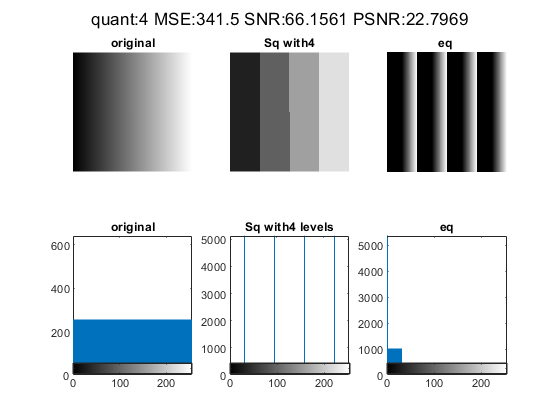

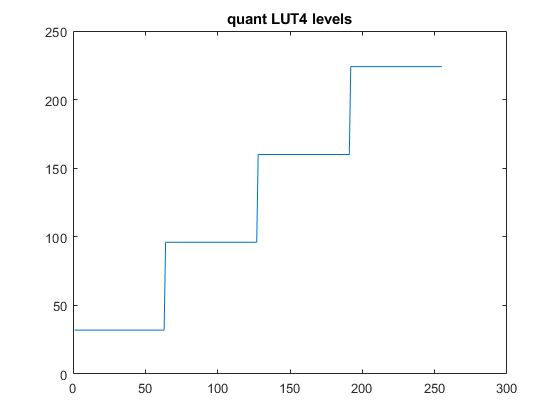

plot_quant(s_ramp, 4);

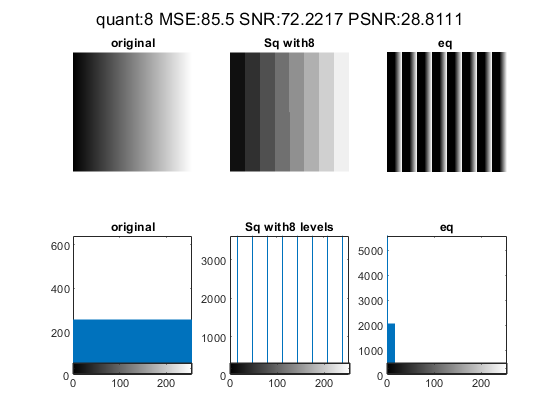

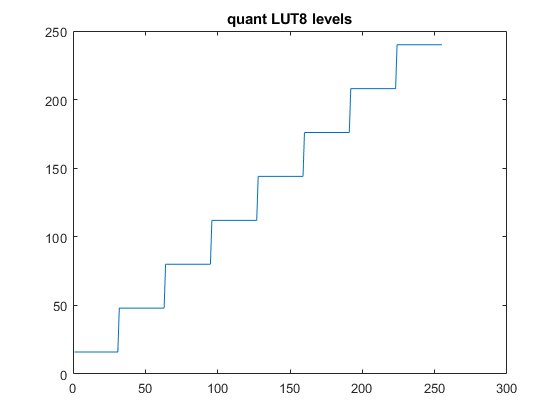

plot_quant(s_ramp, 8);

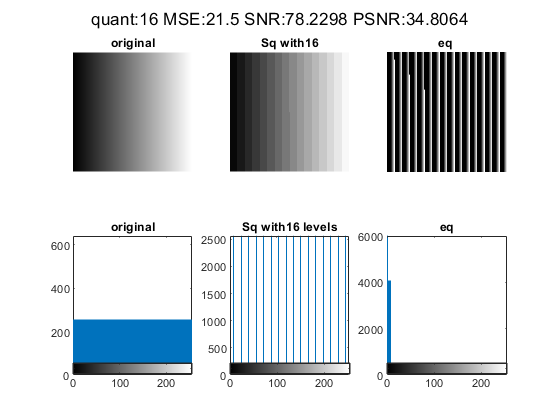

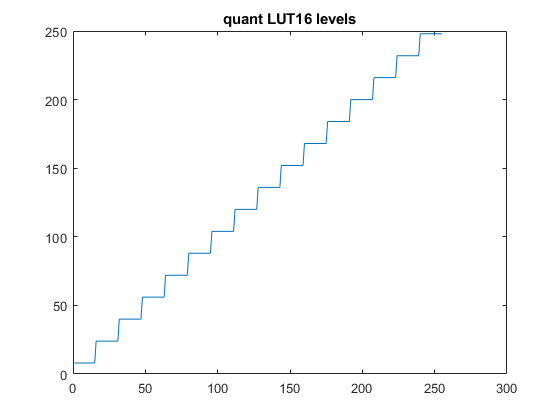

plot_quant(s_ramp, 16);

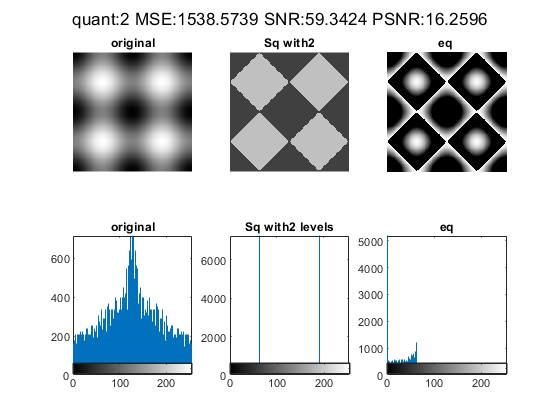

% ramp quant 1,2,3,4
plot_quant(s_2x_2y, 2);

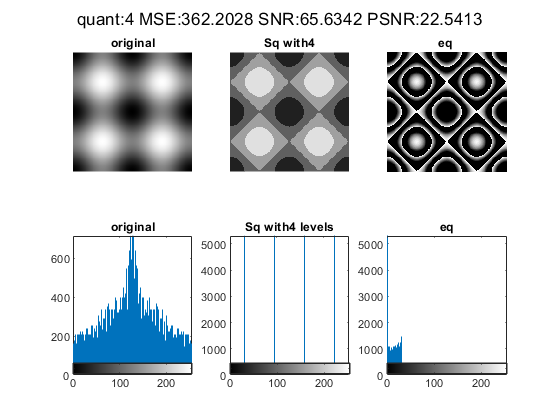

plot_quant(s_2x_2y, 4);

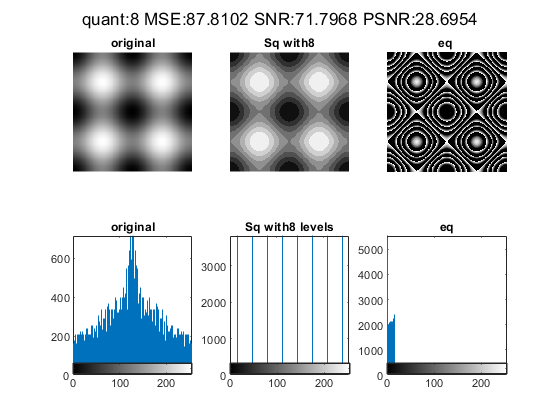

plot_quant(s_2x_2y, 8);

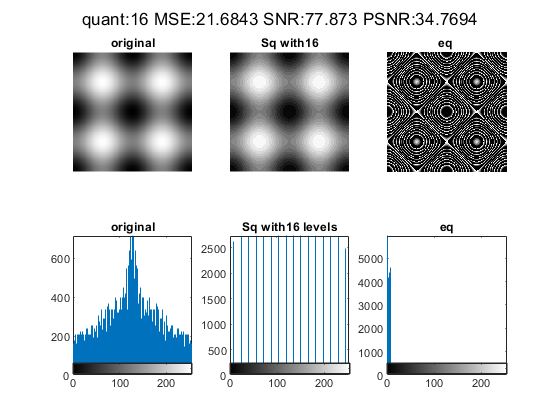

plot_quant(s_2x_2y, 16);

## with noise

Check noise - we chose 0.0159 as the most similar to original.

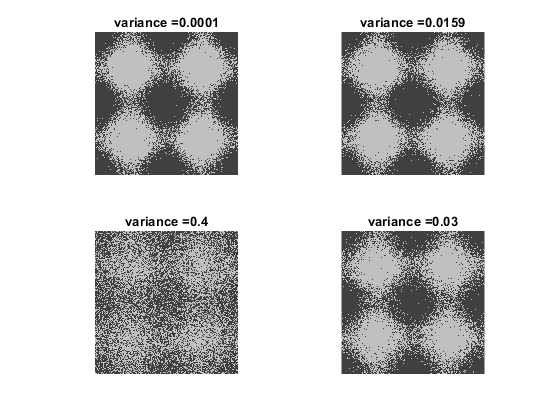

s_2x_2y_noise = imnoise(uint8(s_2x_2y),'gaussian',0,0.0159);
s_2x_2y_noise1 = imnoise(uint8(s_2x_2y),'gaussian',0,0.0159);
s_2x_2y_noise2 = imnoise(uint8(s_2x_2y),'gaussian',0,0.4);
s_2x_2y_noise3 = imnoise(uint8(s_2x_2y),'gaussian',0,0.03);
Q = quant(s_2x_2y_noise, 2);
Q1 = quant(s_2x_2y_noise1, 2);
Q2 = quant(s_2x_2y_noise2, 2);
Q3 = quant(s_2x_2y_noise3, 2);

figure()
subplot(221);imshow(uint8(Q));title('variance =0.0001')
subplot(222);imshow(uint8(Q1));title('variance =0.0159')
subplot(223);imshow(uint8(Q2));title('variance =0.4')
subplot(224);imshow(uint8(Q3));title('variance =0.03')

quatize with noise:

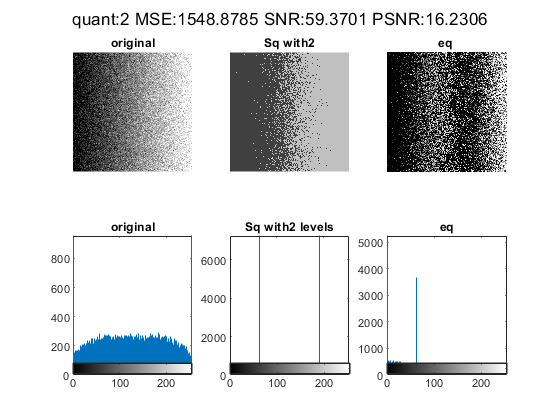


s_ramp_noise = imnoise(uint8(s_ramp),'gaussian',0,0.0159);
s_2x_2y_noise = imnoise(uint8(s_2x_2y),'gaussian',0,0.0159);
plot_quant(s_ramp_noise, 2);

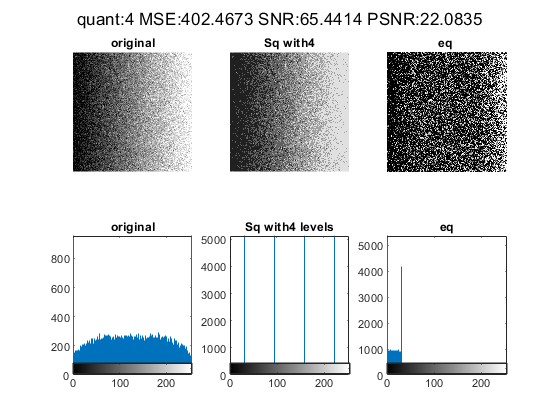

plot_quant(s_ramp_noise, 4);

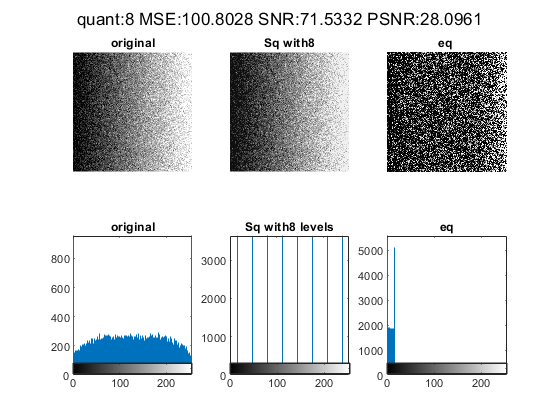

plot_quant(s_ramp_noise, 8);

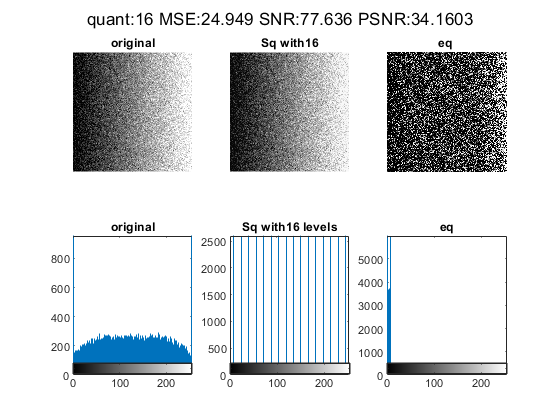

plot_quant(s_ramp_noise, 16);

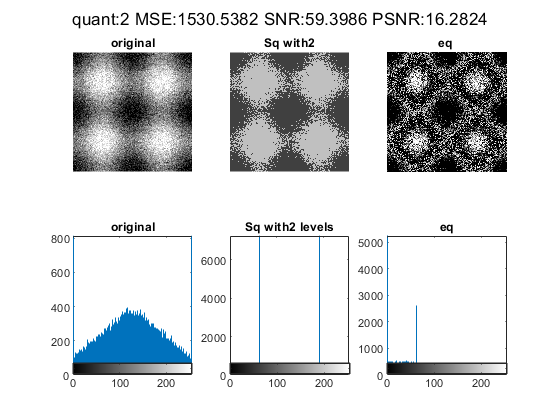

plot_quant(s_2x_2y_noise, 2);

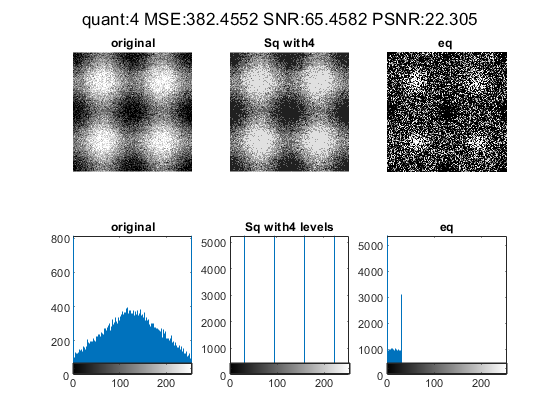

plot_quant(s_2x_2y_noise, 4);

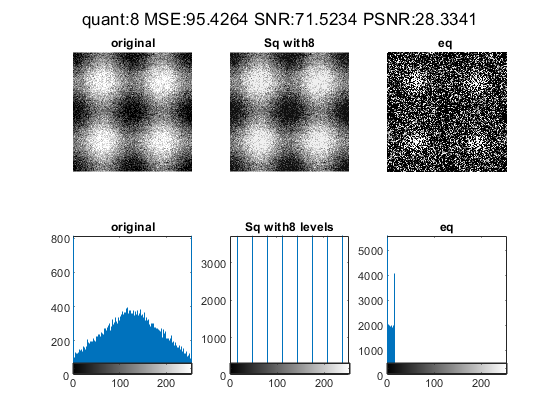

plot_quant(s_2x_2y_noise, 8);

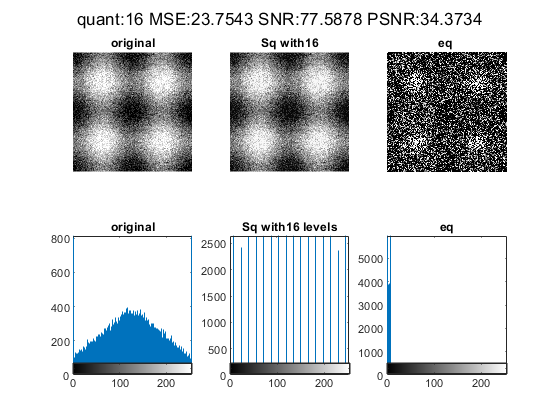

plot_quant(s_2x_2y_noise, 16);

In the noisy picture it can be seen that the measurement results of the MSE, SNR and PSNR are approximately identical to the results obtained in uniform quantization. But it can be seen in the results that the noise caused the contours to break and therefore already at low levels the quantization result is closer to the original image than without the noise. Adding the noise helped to get a better result because the human eye has a sensitivity to this.

## Max-Lloyd - 2.2

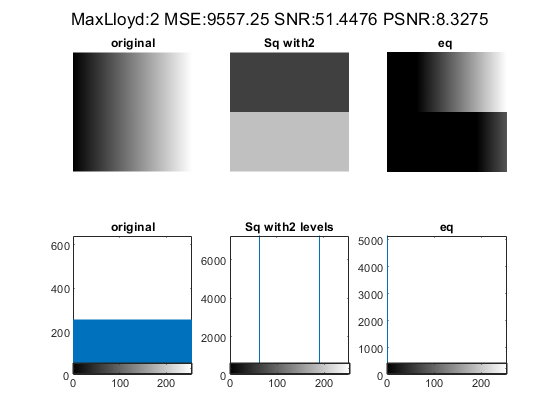


plot_MaxLloyd(s_ramp, 2);

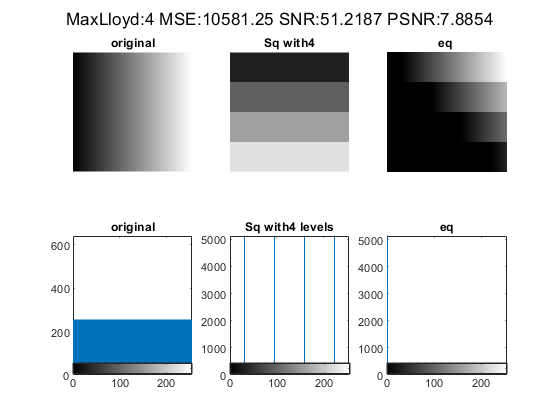

plot_MaxLloyd(s_ramp, 4);

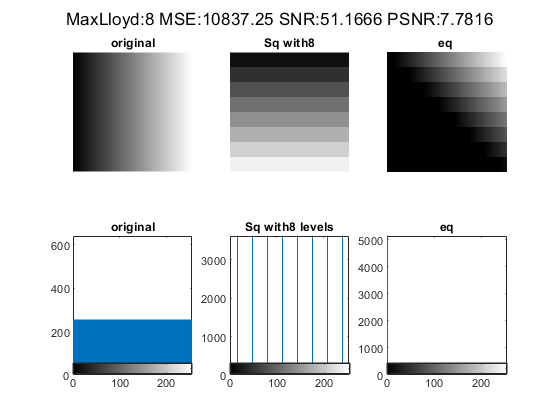

plot_MaxLloyd(s_ramp, 8);

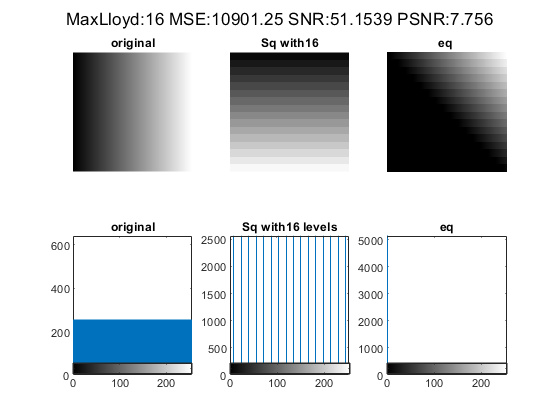

plot_MaxLloyd(s_ramp, 16);range_ramp=0:1:255;

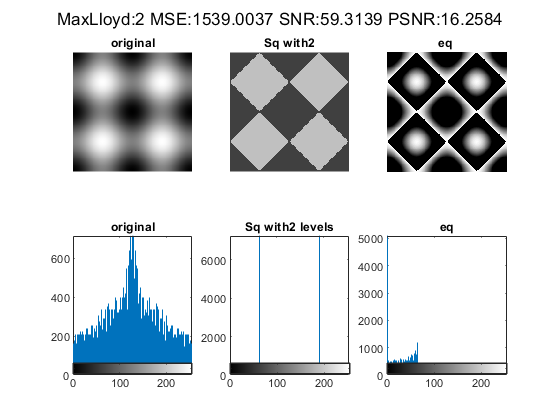

s_ramp = repmat(range_ramp,256,1);
% create sin 2x and 2y img
x = 1:256;
y = 1:256;
y =y';
fs = 256;
ts=1/fs;
fx_y = 2; 
image_x = 127-127*cos(2*pi*fx_y*ts*x);
image_x = repmat(image_x,256,1);
image_y = 127-127*cos(2*pi*fx_y*ts*y);
image_y = repmat(image_y,1,256);
s_2x_2y = uint8((image_x + image_y)/2);range_ramp=0:1:255;
s_ramp = repmat(range_ramp,256,1);
% create sin 2x and 2y img
x = 1:256;
y = 1:256;
y =y';
fs = 256;
ts=1/fs;
fx_y = 2; 
image_x = 127-127*cos(2*pi*fx_y*ts*x);
image_x = repmat(image_x,256,1);
image_y = 127-127*cos(2*pi*fx_y*ts*y);
image_y = repmat(image_y,1,256);
s_2x_2y = uint8((image_x + image_y)/2);
% ramp quant 1,2,3,4
plot_MaxLloyd(s_2x_2y, 2);

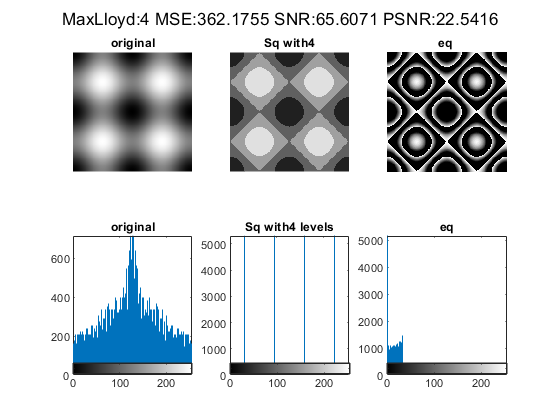

plot_MaxLloyd(s_2x_2y, 4);

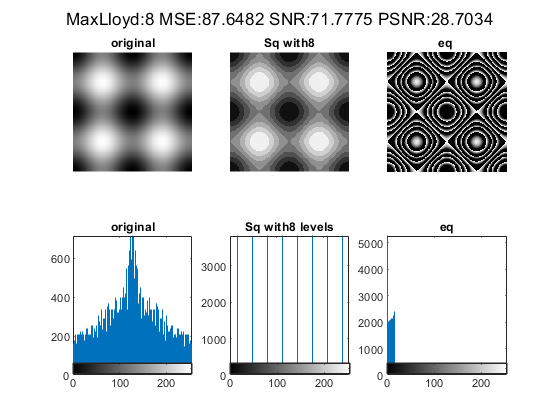

plot_MaxLloyd(s_2x_2y, 8);

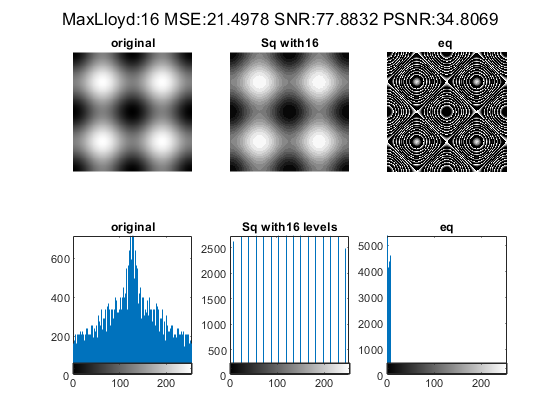

plot_MaxLloyd(s_2x_2y, 16);

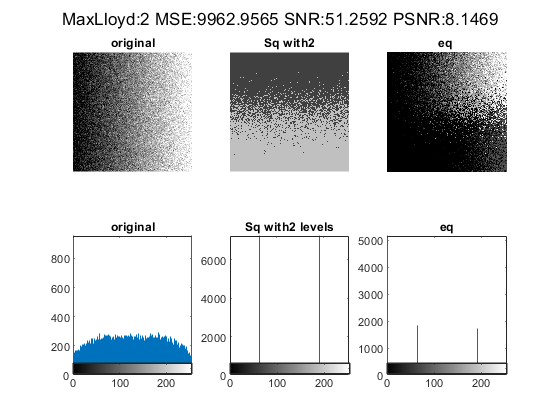



plot_MaxLloyd(s_ramp_noise, 2);

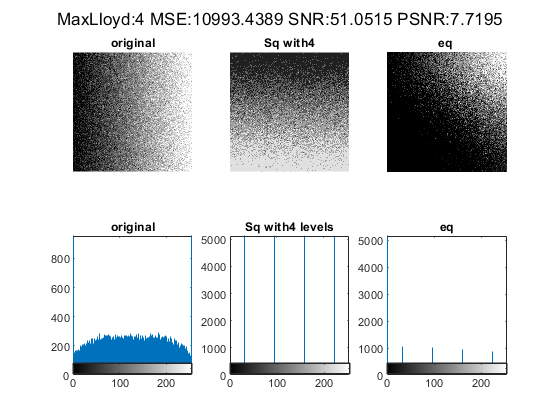

plot_MaxLloyd(s_ramp_noise, 4);

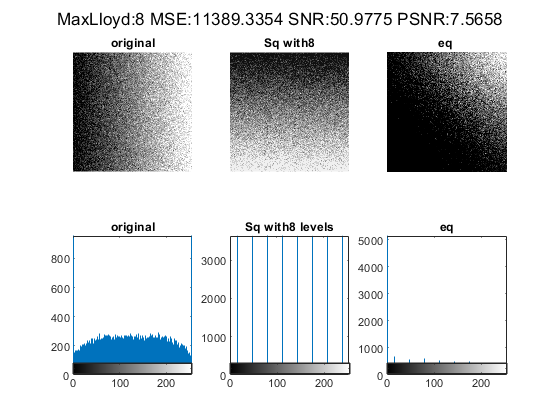

plot_MaxLloyd(s_ramp_noise, 8);

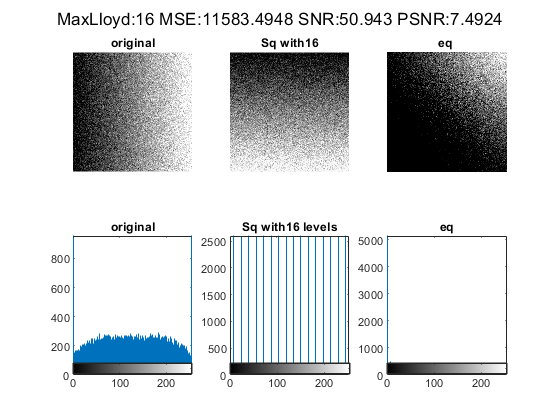

plot_MaxLloyd(s_ramp_noise, 16);

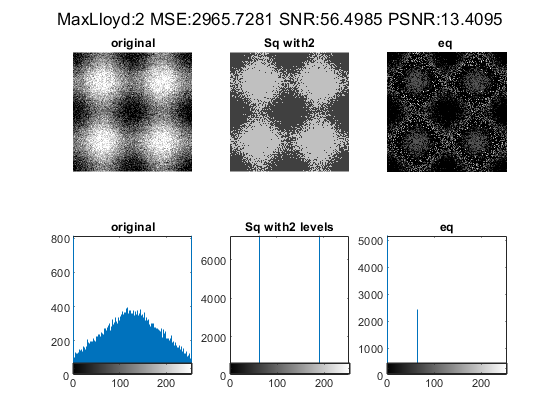

plot_MaxLloyd(s_2x_2y_noise, 2);

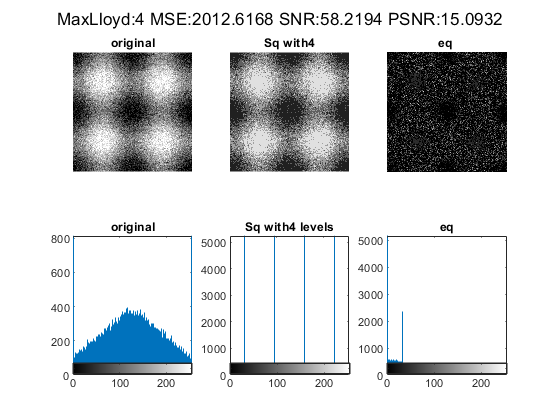

plot_MaxLloyd(s_2x_2y_noise, 4);

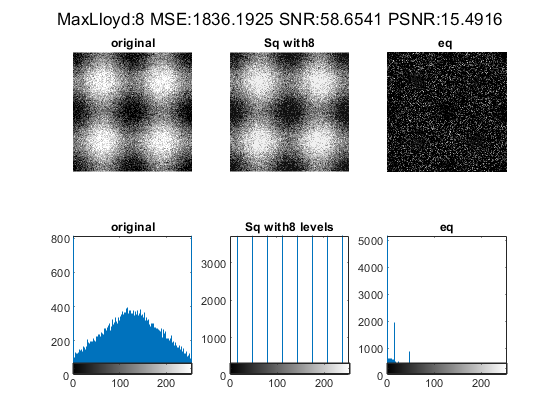

plot_MaxLloyd(s_2x_2y_noise, 8);

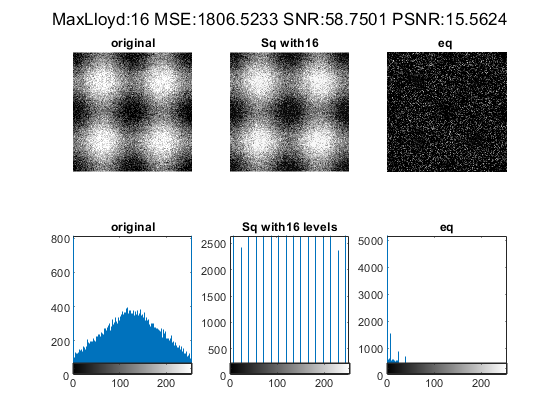

plot_MaxLloyd(s_2x_2y_noise, 16);

# 2.2.3

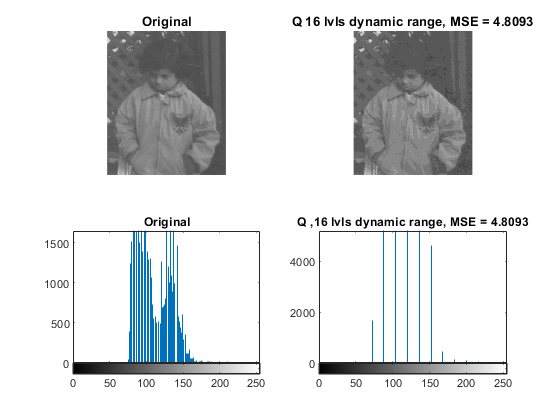

clear all; close all;
image = double(imread('Pout.tif'));
[M N] = size(image); 
Batch=256;
Quan=zeros(256,1);
L=16;
q=Batch/L;
for i=0:255
    Quan(i+1,1)=floor(i/q)*q+q/2;
end
im_q=zeros(M,N);
im_q(:,:)=Quan(image(:,:)+1);
figure;
w=M*N;
err=double(image)-double(im_q);
MSE=(sum(sum(err.^2)))/w;
root_MSE=sqrt(MSE);
subplot(2,2,1);
imshow(uint8(image)); 
title('Original');
subplot(2,2,3);
imhist(uint8(image)); 
title('Original');
subplot(2,2,2); 
imshow(uint8(im_q));
title(['Q 16 lvls dynamic range, MSE = ',num2str(root_MSE)]);
subplot(2,2,4);
imhist(uint8(im_q)); 
title(['Q ,16 lvls dynamic range, MSE = ',num2str(root_MSE)]);

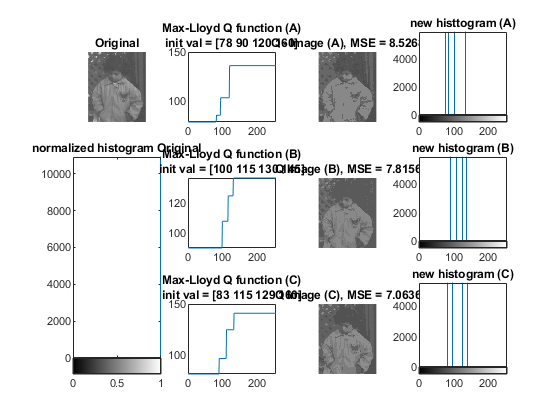

%%
figure
A = [78 90 120 165];
Batch = [100 115 130 145];
Clock = [83 115 129 160];
hist = imhist(image);
norm = hist/(M*N);
subplot(3,4,1); 
imshow(uint8(image)); 
title('Original');
subplot(3,4,[5 9]);
imhist(image); 
title('normalized histogram Original');
% A
[f t x y] = MaxLloyd(image,A);
subplot(3,4,2); 
plot(x,y); 
title({'Max-Lloyd Q function (A)';'init val = [78 90 120 160]'});
for k=1:M
    for l=1:N
        if (image(k,l)<=t(2))
            new_im(k,l) = f(1);
        end
        if (image(k,l)>t(2) && image(k,l)<=t(3))
            new_im(k,l) = f(2);
        end
        if (image(k,l)>t(3) && image(k,l)<=t(4))
            new_im(k,l) = f(3);
        end
        if (image(k,l)>t(4) && image(k,l)<=t(5))
            new_im(k,l) = f(4);
        end
    end
end
w=M*N;
err=double(image)-new_im;
MSE=(sum(sum(err.^2)))/w;
root_MSE=sqrt(MSE);
subplot(3,4,3); 
imshow(uint8(new_im)); 
title(['Q - Image (A), MSE = ',num2str(root_MSE)]);
subplot(3,4,4); 
imhist(uint8(new_im)) ; 
title('new histtogram (A)');
% B
[f t x y] = MaxLloyd(image,Batch);
subplot(3,4,6); 
plot(x,y); 
title({'Max-Lloyd Q function (B)';'init val = [100 115 130 145]'});
for k=1:M
    for l=1:N
        if (image(k,l)<=t(2))
            new_im(k,l) = f(1);
        end
        if (image(k,l)>t(2) && image(k,l)<=t(3))
            new_im(k,l) = f(2);
        end
        if (image(k,l)>t(3) && image(k,l)<=t(4))
            new_im(k,l) = f(3);
        end
        if (image(k,l)>t(4) && image(k,l)<=t(5))
            new_im(k,l) = f(4);
        end
    end
end
w=M*N;
err=double(image)-new_im;
MSE=(sum(sum(err.^2)))/w;
root_MSE=sqrt(MSE);
subplot(3,4,7); 
imshow(uint8(new_im)); 
title(['Q Image (B), MSE = ',num2str(root_MSE)]);
subplot(3,4,8); 
imhist(uint8(new_im)) ; 
title('new histogram (B)');
% C
[f t x y] = MaxLloyd(image,Clock);
subplot(3,4,10); 
plot(x,y); 
title({'Max-Lloyd Q function (C)';'init val = [83 115 129 160]'});
for k=1:M
    for l=1:N
        if (image(k,l)<=t(2))
            new_im(k,l) = f(1);
        end
        if (image(k,l)>t(2) && image(k,l)<=t(3))
            new_im(k,l) = f(2);
        end
        if (image(k,l)>t(3) && image(k,l)<=t(4))
            new_im(k,l) = f(3);
        end
        if (image(k,l)>t(4) && image(k,l)<=t(5))
            new_im(k,l) = f(4);
        end
    end
end
w=M*N;
err=double(image)-new_im;
MSE=(sum(sum(err.^2)))/w;
root_MSE=sqrt(MSE);
 
subplot(3,4,11); 
imshow(uint8(new_im)); 
title(['Q Image (C), MSE = ',num2str(root_MSE)]);

subplot(3,4,12); 
imhist(uint8(new_im)) ; 
title('new histogram (C)');

It can be assumed that the convergence values we obtained at the origin of Max's Lloyd algorithm are more identical to the values in the original image and 

therefore the MSE is lower. In any case it can be seen that compared to uniform quantification the MSE results are significantly smaller.

# Summery:

In the experiment we dealt with sampling, decimation, interpolation, and quantization, using different methods. We examined the different effects of the procedures on the image, and the reconstruction of the source after performing the procedures.

• Sampling, decimation and interpolation

We saw the relationship between the number of samples we take to a space cell and the nature of the reconstruction (a smaller number of samples created effects of distorted reconstruction, and folding. Also, in the experiment it appears that biliary reconstruction produced a better result relative to the other methods.

We have seen that in interpolation, due to the decimation (in calculating operations rounding numbers) we may get a reconstructed image in dimensions different from those of the original image.

• quantization

We examined a number of methods (fixed uniform, optimal uniform, max-Lloyd), when we identified that using a uniform amount, it is very important to examine the dynamic range of the image, in favor of efficient quantization. We also saw how in some cases we would like to add dithering to the image before the quantization, so that the output would look better  clearer to the observer, surprisingly, despite the deterioration in signal to noise ratio and the average error.

We have seen how from some Max Lloyd produces a smaller average error compared to some uniform. 

we saw that Max Lloyd is based on giving a more bits for the common levels in the matrix, and opposite for levels with a lower concentration.

Functions

function [res] = plot_quant (img,lvl)
    quant_s = quant(img, lvl);
    range_uint = 1:255;
    Q = quant(range_uint, lvl);
    [MSE,SNR,EQ,PSNR] = MseSnrQuant(img,quant_s);

    figure();
    sgtitle(['quant:', num2str(lvl) ,' MSE:' , num2str(MSE) ,' SNR:' , num2str(SNR) , ' PSNR:' , num2str(PSNR)]) 

    subplot(231);  imshow(uint8(img)); title('original');
    subplot(232);  imshow(uint8(quant_s)); title(['Sq with' ,num2str(lvl) ]);
    subplot(233); imshow(uint8(EQ),[]); title('eq ' ) ; 
    subplot(234);  imhist(uint8(img)); title('original');
    subplot(235);  imhist(uint8(quant_s)); title(['Sq with' ,num2str(lvl),' levels' ]);
    subplot(236); imhist(uint8(EQ)); title('eq') ; 
    figure()
    plot(Q); title(['quant LUT' , num2str(lvl) ,' levels']);

end

function [res] = plot_MaxLloyd(img,k) 
    img1=0:1:255;
    img1d=img1(:);
    [par1,sig1] = lloyds(img1d,k);
    [ind1,qua1] = quantiz(img1d,par1,sig1);
    mlimg1=vec2mat(qua1,256);
    
    img1d2=img(:);
    [par2,sig2] = lloyds(img1d,k);
    [ind2,qua2] = quantiz(img1d2,par2,sig2);
    mlimg2=vec2mat(qua2,256);
    
    [MSE,SNR,EQ,PSNR] = MseSnrQuant(img,mlimg2);

    figure;
    sgtitle(['MaxLloyd:', num2str(k) ,' MSE:' , num2str(MSE) ,' SNR:' , num2str(SNR) , ' PSNR:' , num2str(PSNR)]) 
    subplot(231);  imshow(uint8(img)); title('original');
    subplot(232);  imshow(uint8(mlimg2)); title(['Sq with' ,num2str(k) ]);
    subplot(233); imshow(uint8(EQ),[]); title('eq ' ) ; 
    subplot(234);  imhist(uint8(img)); title('original');
    subplot(235);  imhist(uint8(mlimg2)); title(['Sq with' ,num2str(k),' levels' ]);
    subplot(236); imhist(uint8(EQ)); title('eq') ; 
    res = mlimg1;
end

function [MSE,SNR,EQ,PSNR] = MseSnrQuant(image,CheckedImage)
    image = double(image);
    CheckedImage = double(CheckedImage);
    EQ=double(image)-double(CheckedImage);
    SE=EQ.^2;
    MSE = immse(image,CheckedImage);
    s=sum(sum(CheckedImage.^2));
    SNR =10*log10(s/MSE);
    PSNR = 10*log10(255^2/MSE);
end

function sq = quant_n(img,k,max_image, min_image)
    delta=max_image/k;
    sq=(floor(double(img)./delta)+min_image)*delta;
end

function sq = quant(img,k)
    delta=256/k;
    sq=(floor(double(img)./delta)+0.5)*delta;
end

function [f,t,x,y] = MaxLloyd(im,D)
    % MAX-LlOYD function
    hist = imhist(uint8(im));
    normhist = hist/numel(im);   
    num_of_iter = 1;
    f = D;
    for k=1:num_of_iter
        
            f1_num = 0;
            f1_denom = 0;
            f2_num = 0;
            f2_denom = 0;
            f3_num = 0;
            f3_denom = 0;
            f4_num = 0;
            f4_denom = 0;
     
            for i=1:f(1)
                r(i) = i;
                P(i) = normhist(r(i));
                f1_num = f1_num + r(i)*P(i);
                f1_denom = f1_denom + P(i);
            end
     
            for i=f(1)+1:f(2)
                r(i) = i;
                P(i) = normhist(r(i));
                f2_num = f2_num + r(i)*P(i);
                f2_denom = f2_denom + P(i);
            end
     
            for i=f(2)+1:f(3)
                r(i) = i;
                P(i) = normhist(r(i));
                f3_num = f3_num + r(i)*P(i);
                f3_denom = f3_denom + P(i);
            end
     
            for i=f(3)+1:f(4)
                r(i) = i;
                P(i) = normhist(r(i));
                f4_num = f4_num + r(i)*P(i);
                f4_denom = f4_denom + P(i);
            end
     
            f1 = f1_num/f1_denom;
            f2 = f2_num/f2_denom;
            f3 = f3_num/f3_denom;
            f4 = f4_num/f4_denom;
            t1 = (f1+f2)/2;
            t2 = (f2+f3)/2;
            t3 = (f3+f4)/2;
     
            f = ceil([f1 f2 f3 f4]); % levels of representation
            t = ceil([1 t1 t2 t3 256]);  % summation of gray levels
            
    end
    x = 1:256;
    y = zeros(1,256);
    y(t(1):t(2)) = f(1);
    y(t(2)+1:t(3)) = f(2);
    y(t(3)+1:t(4)) = f(3);
    y(t(4)+1:t(5)) = f(4);
end


